## AV dual stim behavior for EMREO comparison

Summarizing behavioral data from AV dual target task, for a subset of subjects which also performed the EMREO task.

After reviewing the data from both my project and the EMREO subjects there are only two subjects which exist in both datasets. I imagine that this is not enough crossover to say anything meaningful, but it might give a sense of the kind of things that are available as outputs for comparison.

#### Load and match data

There are different subject numbers for EMREO and AV data. Here I am just hardcoding in the translation between these subject numbers.

From this point forward, subject numbers for the EMREO task will be used.

%Raw data - ended up not needing
%data_dir = '\\ccn-fig.win.duke.edu\users_drive\Mohl\new_projects\CI_behavioral\data';
% s11 =  SS, note that this subject was run on an earlier version of AV and
% so data isnt included in this project
% s15 = load(sprintf('%s\\%s',data_dir,dir(sprintf('%s\\*H07*',data_dir)).name)); %SW
% s15 = s15.tidy_data;
% s15 = s15(s15.valid_tr ==1,:); %exclude invalid trials
% s49 = load(sprintf('%s\\%s',data_dir,dir(sprintf('%s\\*H02*',data_dir)).name)); %RK
% s49 = s49.tidy_data;
% s49 = s49(s49.valid_tr ==1,:); %exclude invalid trials

% Model fit data
model_dir = '\\ccn-fig.win.duke.edu\users_drive\Mohl\new_projects\CI_behavioral\results\modelfits';
s15_model = load(sprintf('%s\\%s',model_dir,dir(sprintf('%s\\*H07_m*',model_dir)).name)); %SW
s15_model = s15_model.m;
s49_model = load(sprintf('%s\\%s',model_dir,dir(sprintf('%s\\*H02_m*',model_dir)).name)); %SW
s49_model = s49_model.m;

model_ind = 4; %this is for the model [1 1 3 1], which is the typical bayesian CI model fit to all the data

These files are tables that have been converted from the original Beethoven format into tidier formats. This also includes a bunch of pre-processed data features like labeling the trials as valid and extracting the saccade endpoints. Here I've already excluded the invalid trials.

The model structure contains the fits for each of the models. The best/most straightforward model is labeled [1 1 3 1], which corresponds to model_ind = 4

I already have code to generate plots from the model files (which also contain the response) so I'm just going to use those. But the raw data is here for future plots.

#### Plot single saccade rate by target separation

Run plots for both subjects. Note that the plot_unity function is defined at the end of the script. This seems to work fine when you are using the run section or run commands in the top menu, but if it doesn't work you might need to copy the function into a new file and add to path. Or just copy the code out.

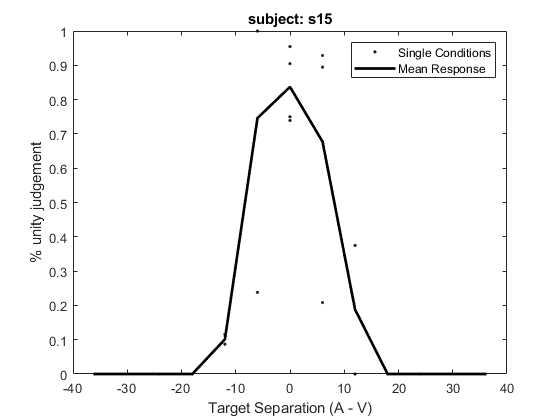

s15_responses = s15_model.responses{model_ind}{1}; %responses contains two cells, 1 is single vs dual, 2 is location
s49_responses = s49_model.responses{model_ind}{1}; %responses contains two cells, 1 is single vs dual, 2 is location
conditions = s15_model.conditions{model_ind};

plot_unity(conditions,s15_responses)
title('subject: s15')

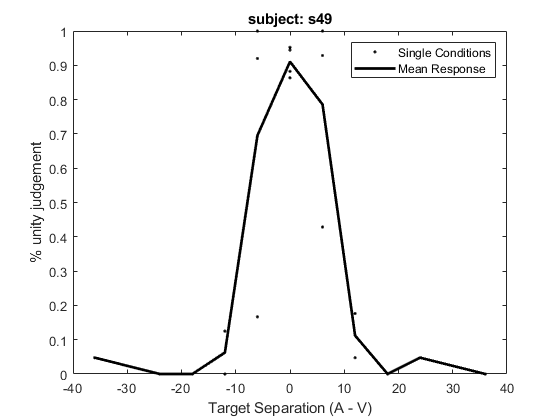

plot_unity(conditions,s49_responses)
title('subject: s49')

I don't see a huge obvious difference between these plots. s49 has a slightly sharper/faster transition between fused (one saccade) and segregate (two saccades). This is backed up with the lower p_common fit in the next section. However the differences are obviously pretty subtle.

#### Look at model fit values for each subject

Models also contain fit values for auditory and visual estimation (based on location response).

s15_fit_vals = s15_model.thetas{model_ind};
s49_fit_vals = s49_model.thetas{model_ind};
fit_val_labels = s15_model.fitoptions.parameter_names;

fit_val_table = array2table([s15_fit_vals;s49_fit_vals]);
fit_val_table.Properties.RowNames = {'s15','s49'};
fit_val_table.Properties.VariableNames = fit_val_labels(1:5);
fit_val_table

fit_val_table = 2×5 table
           A_sig     V_sig     prior_sig    p_common    lambda_uni
           ______    ______    _________    ________    __________

    s15    3.1968    1.4981     15.287      0.72305     0.0069103 
    s49    3.9385    1.4384     26.158       0.5303     0.0015701 


**A_sig**: standard deviation of auditory component

**V_sig**: standard deviation of visual component

**prior_sig**: standard deviation of central normal prior. A smaller value indicates a stronger compressive bias (saccades are biased towards the center).

**p_common**: prior probability of judging the targets as 'same'. A high value indicates a bias towards reporting a fused estimate. the 'true' value would be ~0.5.

**lambda_uni**: lapse rate

These are MAP estimates, so they are just point estimates of the actual values. To get a sense of the variance around these points I would need to do more model runs which takes a while so we can decide if that's an important thing to do in the future.

Looking at these values they don't look all that different. s15 has a higher p_common, which corresponds with a higher tendency to bind the two stimuli together. But without a variance estimate on this it is a little hard to say anything concrete.

#### Functions

Here I am copying a function that I had already written. The inputs of this function are an array of conditions [A1 V1; A2n V2; ... An, Vn], an array of responses [n single saccades; n dual saccades]

function plot_unity(conditions,responses)
%convert from target values in conditions to scalar separation value
deltaAV = conditions(:,1)-conditions(:,2);
%convert responses to percentages
responses = responses./ sum(responses,2);
%group by delta values
[gav,avlabels] = findgroups(deltaAV);
mean_resp = splitapply(@mean, responses(:,1),gav);
mean_sd = splitapply(@std,responses(:,1),gav);

plot(deltaAV,responses(:,1),'.k','MarkerSize',5)
hold on
%errorbar(avlabels,mean_resp,mean_sd,'k','LineWidth',2);
plot(avlabels,mean_resp,'k','LineWidth',2);
hold off
legend('Single Conditions','Mean Response')
xlabel('Target Separation (A - V)')
ylabel('% unity judgement')
end